clc; clear;

stik = 40;     % Antal stikprøver
tests = 100;     % Antal terningekast / udtagelser af stikprøven
test_range = [30, 35];
step = 0.25;

ms = zeros(1, stik);
Y = zeros(stik, tests);

for i = 1:stik
    for j = 1:tests
        Y(i,j) = randi(test_range, 1);
    end
    ms(i) = mean(Y(i,:));
end


histogram(ms, min(test_range):step:max(test_range), "Normalization","pdf")
hold on

% Den gennemsnitlige afvigelse
mean_gns = mean(ms)

mean_gns = 32.5355

stdafv = std(ms, 1)

stdafv = 0.1582

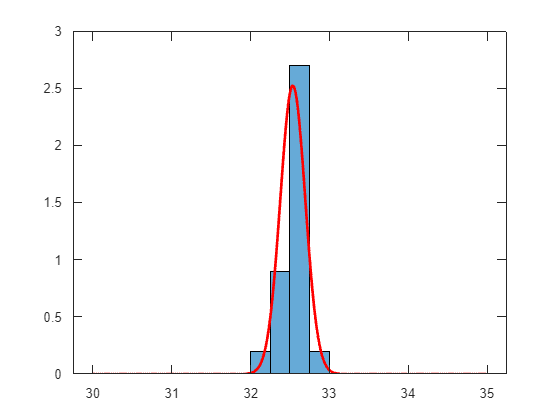


% PLotte fordelingen oveni
dist = makedist("Normal","mu",mean_gns,"sigma",stdafv);
x = linspace(min(test_range), max(test_range), 1000);

df = pdf(dist, x);

plot(x, df, Color="red", LineStyle="-", LineWidth=2)
hold off





dist2 = makedist("Normal", "mu",mean_gns,"sigma",stdafv)

dist2 =   NormalDistribution

  Normal distribution
       mu =  32.5355
    sigma = 0.158176



df2 = random(dist2, stik*tests, 1);


[h,p,stats] = chi2gof(df2,'Alpha', 0.05)

h = 0

p = 0.9499

stats = struct with fields:
    chi2stat: 1.6366
          df: 6
       edges: [31.9436 32.1673 32.2792 32.3911 32.5029 32.6148 32.7267 32.8386 32.9504 33.0623]
           O: [37 170 503 971 1120 765 328 93 13]
           E: [37.9733 167.7642 513.1651 961.3685 1.1038e+03 776.7955 334.9590 88.4229 15.7658]


clc; clear;

step = 7;

data = importdata("Log Data 18-04-2023 09.22.38.txt");

ohms = data.data(:, 2);


mean_gns = mean(ohms)

mean_gns = 3.2140e+04

stdafv = std(ohms, 1)

stdafv = 35.0025




dist2 = makedist("Normal", "mu",mean_gns,"sigma",stdafv)

dist2 =   NormalDistribution

  Normal distribution
       mu = 32139.6
    sigma = 35.0025



df2 = random(dist2, 100, 1);

[h,p,stats] = chi2gof(df2,'Alpha', 0.05)

h = 0

p = 0.4917

stats = struct with fields:
    chi2stat: 4.4126
          df: 5
       edges: [3.2055e+04 3.2090e+04 3.2107e+04 3.2124e+04 3.2141e+04 3.2158e+04 3.2176e+04 3.2193e+04 3.2227e+04]
           O: [6 13 16 14 22 12 11 6]
           E: [7.8016 9.7848 15.2678 18.8749 18.4880 14.3479 8.8220 6.6130]


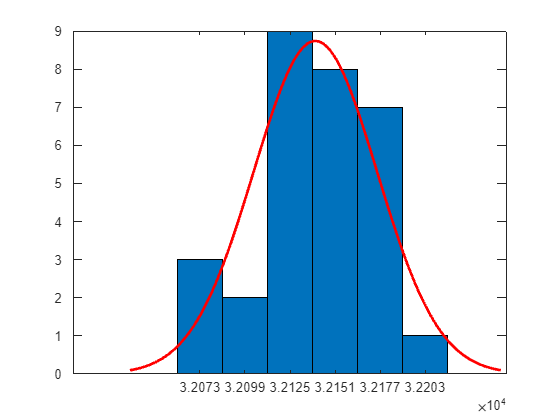


histfit(ohms)

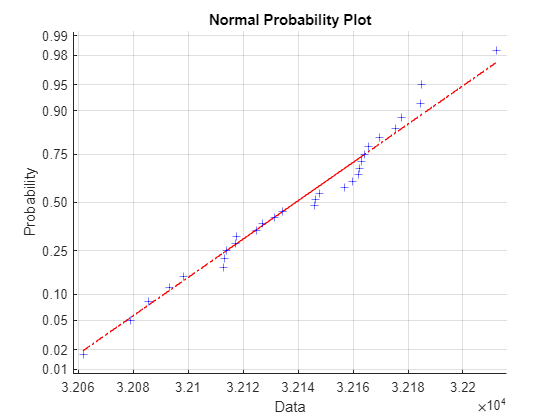



normplot(ohms)

clc; clear;

d1 = importdata("Log-Data-17-04-2023-12.54.19.txt");
d2 = importdata("Log-Data-17-04-2023-15.20.19.txt");


d1_ohm = d1.data(:, 2)';
d1_volt = d2.data(:, 2)';



deskripts([d1_ohm;d1_volt],["Data 1", "Data 2"])

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Data 1"       17220       279.98          16.733              30     
    "Data 2"       17194       206.96          14.386              30     



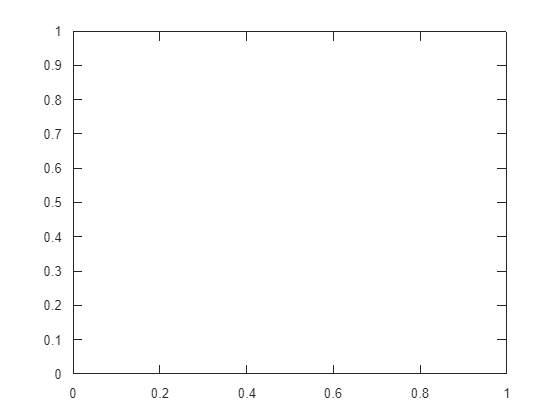


n = 30;

plothandle = plot(NaN, NaN);

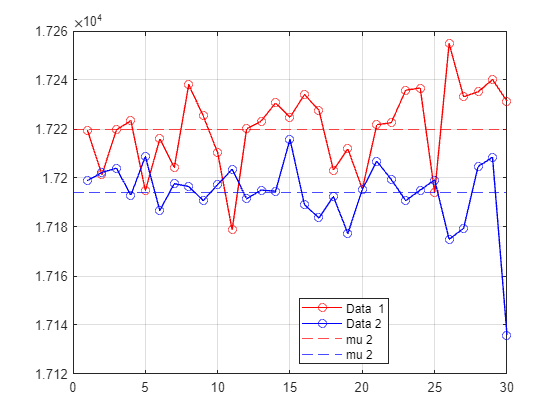




plot(1:30, d1_ohm, '-o', Color='r',DisplayName="Data  1"), grid("on")
hold on

plot(1:30, d1_volt, '-o',Color='b',DisplayName="Data 2")

yline(17220,'--', Color='r',DisplayName="mu 2")
yline(17194,'--', Color='b',DisplayName="mu 2")

legend('show', 'location','best')

hold off


clc; clear;

d1 = importdata("Log-Data-17-04-2023-12.54.19.txt");
d2 = importdata("Log-Data-17-04-2023-15.20.19.txt");


d1_ohm = d1.data(:, 2)';
d1_volt = d2.data(:, 2)';



deskripts([d1_ohm;d1_volt],["Data 1", "Data 2"])

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Data 1"       17220       279.98          16.733              30     
    "Data 2"       17194       206.96          14.386              30     



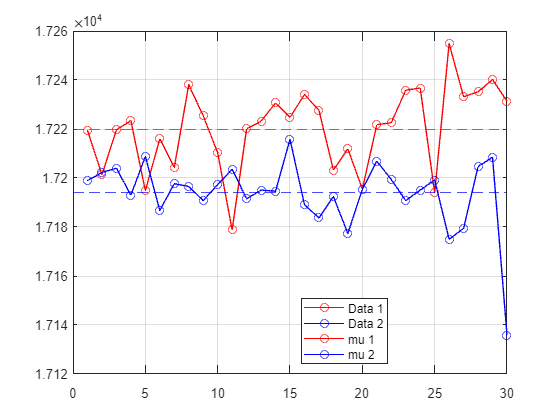


n = 30;

for i = 1:n

plot(1:i, d1_ohm(1:i), '-o', Color='r'), grid("on")
hold on

plot(1:i, d1_volt(1:i), '-o',Color='b')

drawnow()

pause(0.1)

end
yline(17220,'--', Color='r')
yline(17194,'--', Color='b')

legend("Data 1", "Data 2", "mu 1", "mu 2", Location="best")

hold off

disp("Interpolation")

Interpolation


clc; clear;

d1 = importdata("Log Data 17-04-2023 12.54.19.txt");
d2 = importdata("Log Data 17-04-2023 15.20.19.txt");


d1_ohm = [d1.data(:, 2)',d2.data(:, 2)']

d1_ohm = 1.0e+04 *

    1.7219    1.7201    1.7220    1.7223    1.7195    1.7216    1.7204    1.7238    1.7225    1.7210    1.7179    1.7220    1.7223    1.7231    1.7225    1.7234    1.7228    1.7203    1.7212    1.7196    1.7222    1.7223    1.7236    1.7237    1.7194    1.7255    1.7233    1.7235    1.7240    1.7231    1.7199    1.7202    1.7204    1.7193    1.7209    1.7187    1.7198    1.7197    1.7191    1.7197    1.7204    1.7191    1.7195    1.7195    1.7216    1.7189    1.7184    1.7192    1.7177    1.7195


d1_volt = [d1.data(:,1)',d2.data(:, 1)']

d1_volt =     3.1625    3.1613    3.1625    3.1628    3.1609    3.1623    3.1615    3.1637    3.1628    3.1619    3.1597    3.1625    3.1627    3.1633    3.1629    3.1634    3.1631    3.1614    3.1620    3.1608    3.1627    3.1627    3.1636    3.1637    3.1608    3.1649    3.1635    3.1636    3.1638    3.1633    3.1614    3.1615    3.1617    3.1609    3.1620    3.1605    3.1612    3.1611    3.1607    3.1612    3.1616    3.1608    3.1610    3.1610    3.1624    3.1606    3.1603    3.1608    3.1598    3.1611



d2_ohm = d2.data(:, 2)';
d2_volt = d2.data(:, 1)';



% Data
% Afhængig variabel
depend1 = d1_ohm;
% Uafhængig variabel
independ1 = d1_volt;

% Afhængig variabel
depend2 = d2_ohm;
% Uafhængig variabel
independ2 = d2_volt;




brd_lin =     3.1573    3.1529    3.1491    3.1457    3.1429    3.1405    3.1386    3.1371    3.1360    3.1352    3.1348    3.1346    3.1348    3.1353    3.1359    3.1368    3.1379    3.1391    3.1405    3.1419    3.1435    3.1451    3.1467    3.1484    3.1500    3.1516    3.1532    3.1546    3.1559    3.1571    3.1581    3.1589    3.1595    3.1598    3.1599    3.1597    3.1598    3.1603    3.1604    3.1603    3.1603    3.1603    3.1604    3.1606    3.1607    3.1605    3.1608    3.1608    3.1607    3.1609


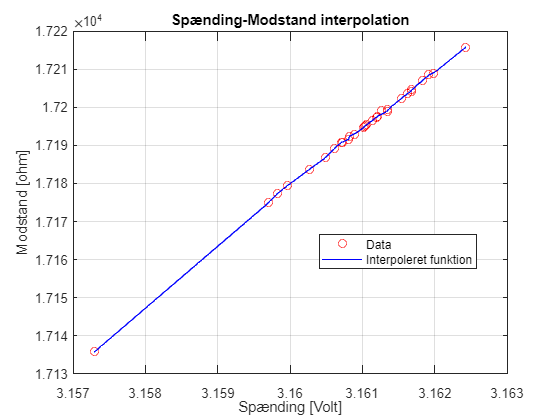

% Afhængig variabel
depend1 = d2_ohm;
% Uafhængig variabel
independ1 = d2_volt;


% Linspace til plot
dependlin1 = linspace(min(depend1), max(depend1));

% Linear fit
brd_lin = interp1(depend1, independ1, dependlin1, 'linear') ;

% Data plottes
plot(independ1,depend1, 'ro', 'DisplayName', 'Data'), grid("on")
title('Spænding-Modstand interpolation')
xlabel('Spænding [Volt]')
ylabel('Modstand [ohm]')

hold on

% Fit plottes
plot(brd_lin,dependlin1,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off